# **Chapter 14 Mini Quiz (Mini Quiz Lec09) [ALL CORRECT]**

**Mini quiz -- Power Linearization**

**Data**

x = [1.0000    1.2000    1.4000    1.6000    1.8000    2.0000    2.2000    2.4000    2.6000    2.8000    3.0000]

x =     1.0000    1.2000    1.4000    1.6000    1.8000    2.0000    2.2000    2.4000    2.6000    2.8000    3.0000


y = [3.2888    7.6111   11.9175   22.3415   35.8022   33.2350   71.6824   43.5441  90.5842   74.6333  94.7754]

y =     3.2888    7.6111   11.9175   22.3415   35.8022   33.2350   71.6824   43.5441   90.5842   74.6333   94.7754


**Plot data**

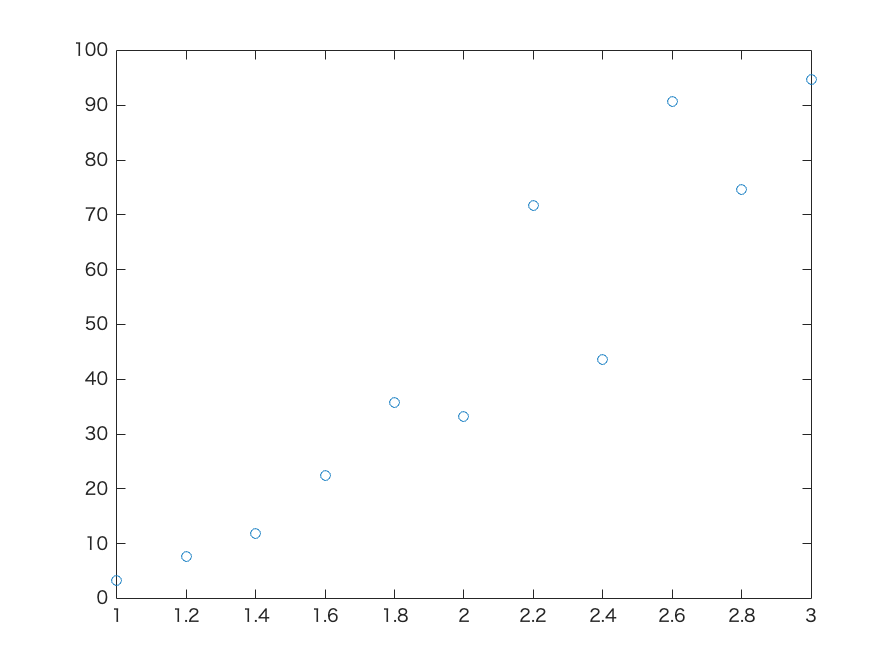

plot(x, y, 'o')
hold off

**Transform data**

new_x = log10(x)

new_x =          0    0.0792    0.1461    0.2041    0.2553    0.3010    0.3424    0.3802    0.4150    0.4472    0.4771


new_y = log10(y)

new_y =     0.5170    0.8814    1.0762    1.3491    1.5539    1.5216    1.8554    1.6389    1.9571    1.8729    1.9767


**Perform linear regression & plot dataset + fitted line**

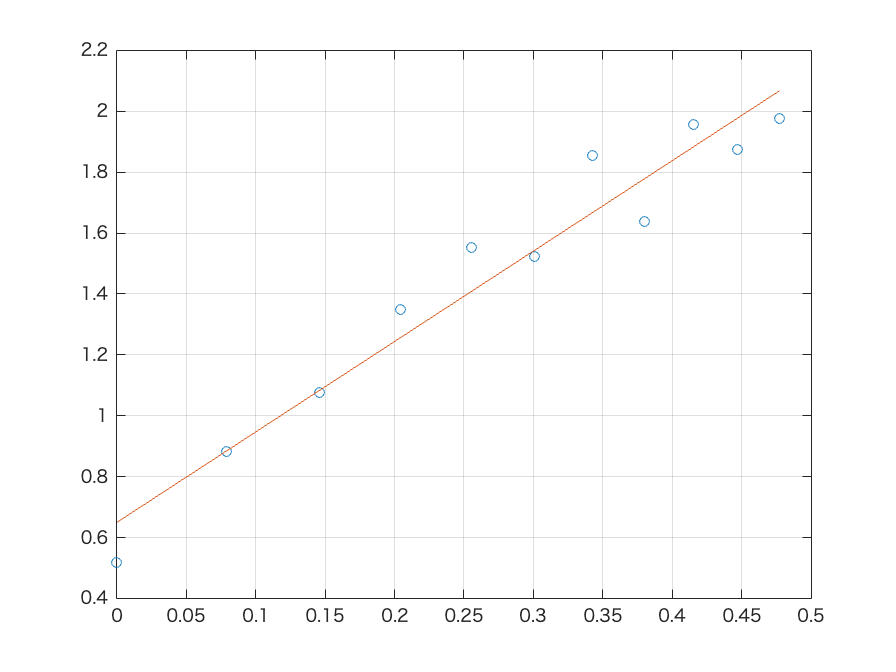

a =     2.9712    0.6496


r2 = 0.9435

[a, r2] = linregr(new_x, new_y)

slope = a(1)

slope = 2.9712

intercept = a(2)

intercept = 0.6496

**Compute parameters of nonlinear equation from the fitted line**

alpha = 10^intercept

alpha = 4.4625

beta = slope

beta = 2.9712

**Plot the original data with the best fit nonlinear curve**

xplot = linspace(min(x), max(x), 100)

xplot =     1.0000    1.0202    1.0404    1.0606    1.0808    1.1010    1.1212    1.1414    1.1616    1.1818    1.2020    1.2222    1.2424    1.2626    1.2828    1.3030    1.3232    1.3434    1.3636    1.3838    1.4040    1.4242    1.4444    1.4646    1.4848    1.5051    1.5253    1.5455    1.5657    1.5859    1.6061    1.6263    1.6465    1.6667    1.6869    1.7071    1.7273    1.7475    1.7677    1.7879    1.8081    1.8283    1.8485    1.8687    1.8889    1.9091    1.9293    1.9495    1.9697    1.9899


yplot = alpha .* (xplot .^ beta)

yplot =     4.4625    4.7357    5.0198    5.3150    5.6215    5.9394    6.2691    6.6107    6.9645    7.3306    7.7092    8.1005    8.5049    8.9224    9.3533    9.7977   10.2560   10.7283   11.2147   11.7156   12.2311   12.7614   13.3068   13.8674   14.4435   15.0352   15.6428   16.2665   16.9064   17.5628   18.2360   18.9260   19.6331   20.3575   21.0995   21.8592   22.6368   23.4325   24.2466   25.0792   25.9306   26.8009   27.6904   28.5993   29.5278   30.4760   31.4442   32.4326   33.4414   34.4708


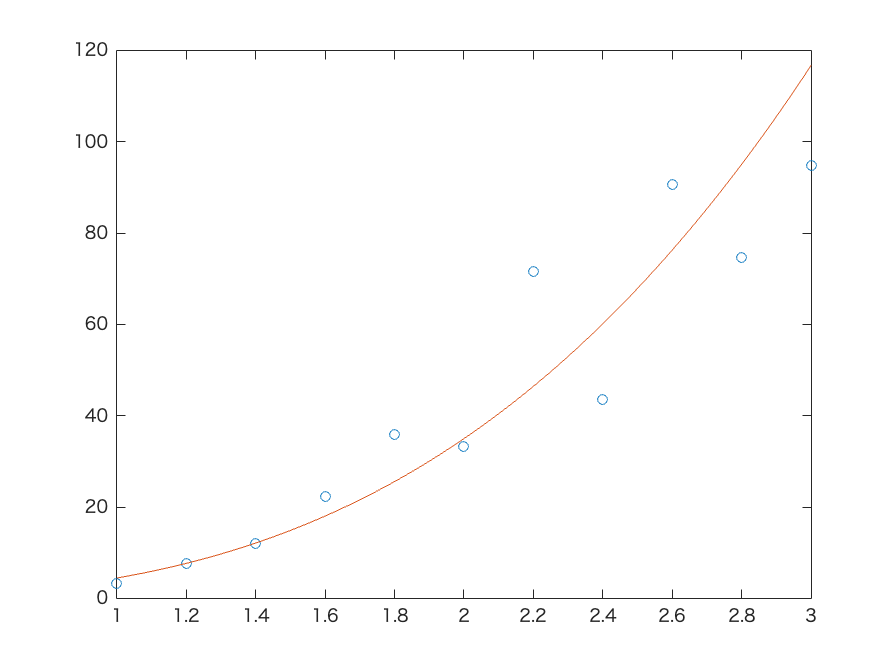

plot(x, y, 'o', xplot, yplot)

**Predict the value of y for the given x**

xtest = 1.5

xtest = 1.5000

ytest = alpha .* (xtest .^ beta)

ytest = 14.8858